# *Transfer Learning*

*Transfer Learning is the process of modifing a existing Neural Network convinent to our application.*

*Transfer learning is an efficient solution for many problems. Training requires some data and computer time, but much less than training from scratch, and the result is a network suited to your specific problem.*

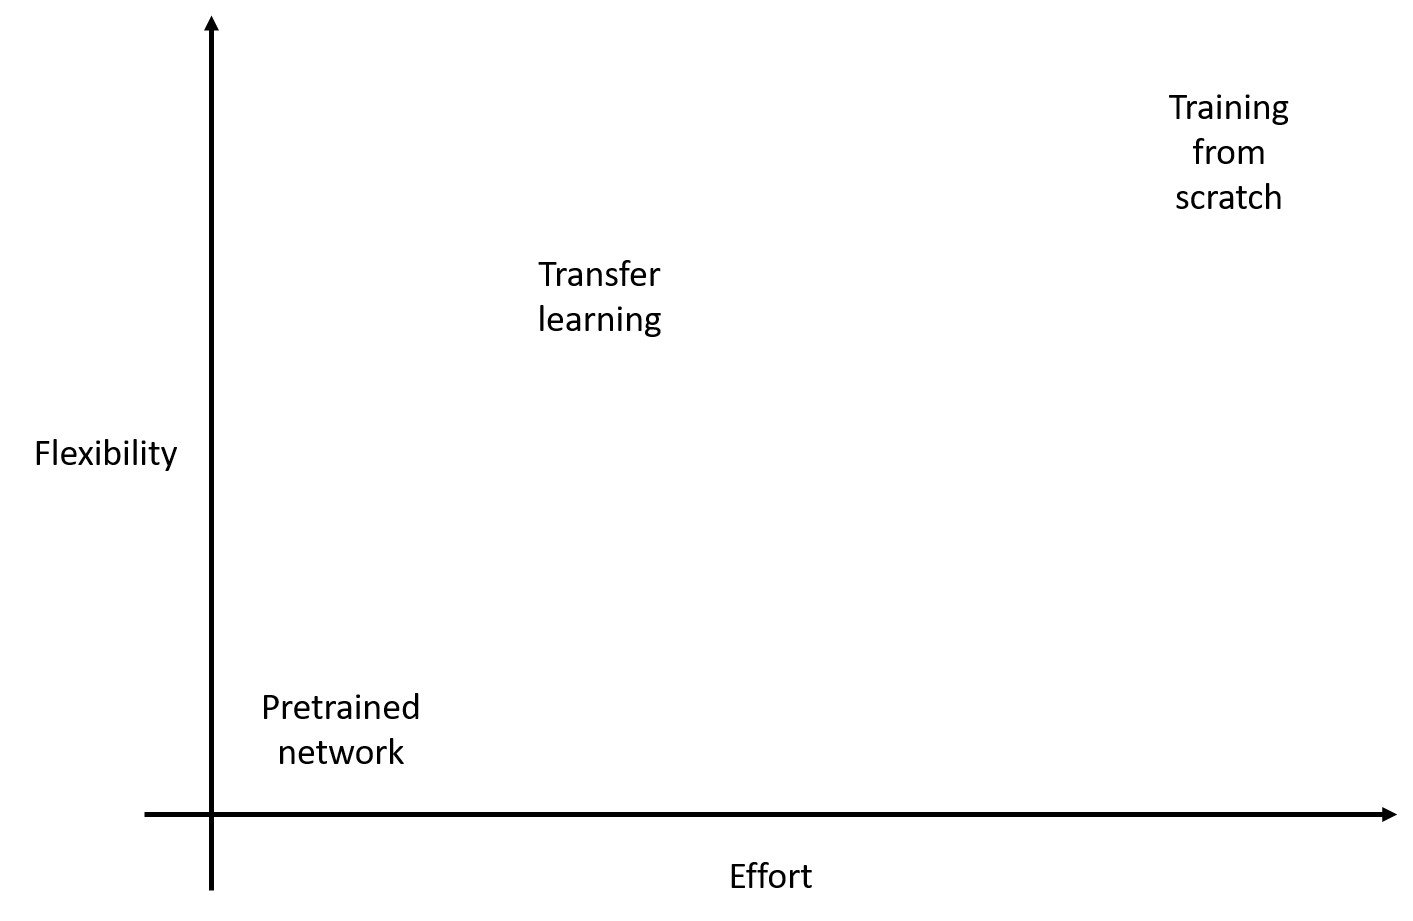

### *Typical workflow for transfer learning*

*To perform transfer learning, you need to create three components:*

*An array of layers representing the network architecture. For transfer learning, this is created by modifying a pre-existing network such as AlexNet.*

*Images with known labels to be used as training data. This is typically provided as a datastore.*

*A variable containing the options that control the behavior of the training algorithm.*

*These three components are provided as the inputs to the trainNetwork function which returns the trained network as output.*

*You should test the performance of the newly trained network. If it is not adequate, typically you should try adjusting some of the training options and retraining.*

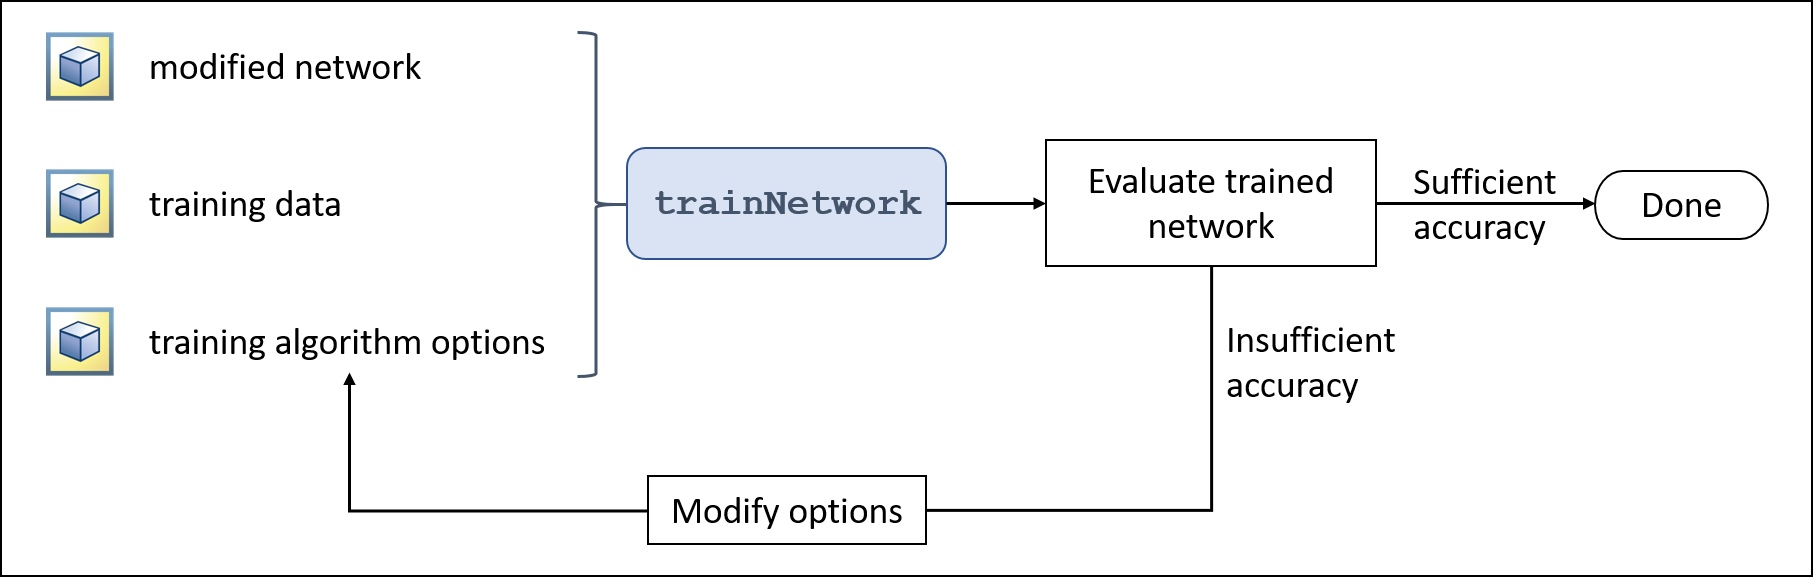

* Now we will be importing "AlexNet" with a convinent name(deepnet) for our usage. Layers function will display the layers in the network.(Remove " ; " to see the output)*

deepnetwork = alexnet

deepnetwork =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


layers = deepnetwork.Layers

layers =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0

Now we will view the 2 images of cats in train folder and print their size.

img1 = imread('cat.1.jpg');
size(img1)

ans =    280   300     3


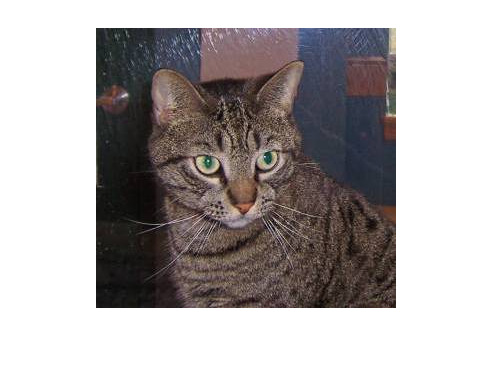

imshow(img1)


img = imread('cat.2.jpg');
size(img)

ans =    396   312     3


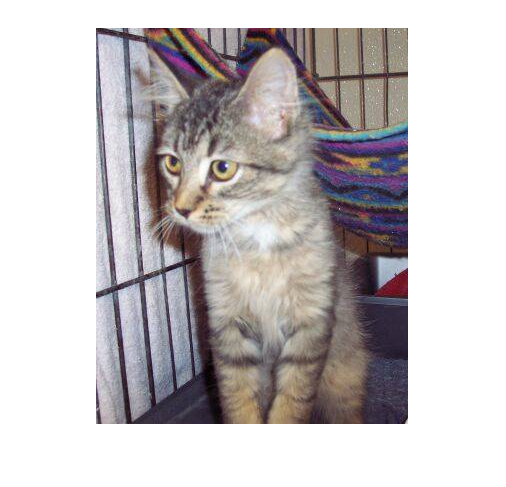

imshow(img)

It can be observed that sizes of 2 images should be same as size of the input layer of "AlexNet". The below code gives the size of input layer.

Input_image_size = layers(1).InputSize

Input_image_size =    227   227     3


## Pre-processing Images in a Datastore

To classify images with a convolutional neural network, each image needs to have the size specified by the network's input layer. 

Images usually require simple preprocessing before they can be classified. You can preprocess your images individually, but it is common to perform the same preprocessing steps on the entire data set. It is more efficient to apply these steps to the entire datastore.

It can be time consuming to process each image individually. If you want to use an image datastore, you also need to save the processed images to a folder. For large data sets, saving a duplicate of your files can take up a lot of space.

It can be time consuming to process each image individually. If you want to use an image datastore, you also need to save the processed images to a folder. For large data sets, saving a duplicate of your files can take up a lot of space.

You can perform basic preprocessing with the augmentedImageDatastore function, which takes an image datastore and an image size as an input.

Creates a Datastore by not only taking images in the folder but also images in subfolders and labels them according to name of subfolder.

ds_pets = imageDatastore('Images','IncludeSubfolders',true,'LabelSource','foldernames')

ds_pets =   ImageDatastore with properties:

                       Files: {
                              ' .../Image-Processing/Matlab Practice/Cats and Dogs/Images/Cats/cat.0.jpg';
                              ' .../Image-Processing/Matlab Practice/Cats and Dogs/Images/Cats/cat.1.jpg';
                              ' .../Image-Processing/Matlab Practice/Cats and Dogs/Images/Cats/cat.10.jpg'
                               ... and 2997 more
                              }
                      Labels: [Cats; Cats; Cats ... and 2997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


 Pet_Categories = ds_pets.Labels       %----  Prints each Category of Image

Pet_Categories = 3000×1 categorical array
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 


Entire data set is split into Training and Validation Data. Images in SubFolders will also be divided. "0.8" indicates the ratio of total belonging to TrainImgs.

[trainImgs,testImgs] = splitEachLabel(ds_pets,0.8,'randomized')

trainImgs =   ImageDatastore with properties:

                       Files: {
                              ' .../Image-Processing/Matlab Practice/Cats and Dogs/Images/Cats/cat.0.jpg';
                              ' .../Image-Processing/Matlab Practice/Cats and Dogs/Images/Cats/cat.10.jpg';
                              ' .../Matlab Practice/Cats and Dogs/Images/Cats/cat.100.jpg'
                               ... and 2397 more
                              }
                      Labels: [Cats; Cats; Cats ... and 2397 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


testImgs =   ImageDatastore with properties:

                       Files: {
                              ' .../Image-Processing/Matlab Practice/Cats and Dogs/Images/Cats/cat.1.jpg';
                              ' .../Matlab Practice/Cats and Dogs/Images/Cats/cat.105.jpg';
                              ' .../Matlab Practice/Cats and Dogs/Images/Cats/cat.106.jpg'
                               ... and 597 more
                              }
                      Labels: [Cats; Cats; Cats ... and 597 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


trainImgs = augmentedImageDatastore([227 227],trainImgs)

trainImgs =   augmentedImageDatastore with properties:

             NumObservations: 2400
                       Files: {2400×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


%trainImgs.ReadFcn = @(loc)imresize(imread(loc),[227 227]);

Actual Labels of Test Images

test_labels = testImgs.Labels

test_labels = 600×1 categorical array
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 
     Cats 


testImgs = augmentedImageDatastore([227 227],testImgs)

testImgs =   augmentedImageDatastore with properties:

             NumObservations: 600
                       Files: {600×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


%testImgs.ReadFcn = @(loc)imresize(imread(loc),[227 227]);

Returns no.of different classes of Images

numClasses = numel(categories(ds_pets.Labels))

numClasses = 2

Now we will modify the AlexNet Layers to our convinence.  We now create fullyconnectedlayer having (no.of classes) neurons as output.

fclayer = fullyConnectedLayer(numClasses)

fclayer =   FullyConnectedLayer with properties:

          Name: ''

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 2

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


23rd layer of AlexNet  should replaced by our layer

layers(23) = fclayer

layers =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0

You can use the classificationLayer function to create a new output layer for an image classification network. You can create new layers and overwrite an existing layer with the new layer in a single command.

layers(end) = classificationLayer

layers =   25x1 Layer array with layers:

     1   'data'    Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'   Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'   ReLU                          ReLU
     4   'norm1'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'   Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'   ReLU                          ReLU
     8   'norm2'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
 

## Training and Evaluating Results

Now setting Training Options

options = trainingOptions('adam','InitialLearnRate',0.005,'MaxEpochs',20,'ExecutionEnvironment',"gpu","MiniBatchSize",32)

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 0.0050
     LearnRateScheduleSettings: [1×1 struct]
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 20
                 MiniBatchSize: 32
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: []
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'gpu'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 'none'
                SequenceLength: 'longest'
          SequencePaddingValue: 

Performing Training

warning off parallel:gpu:device:DeviceLibsNeedsRecompiling
try
    gpuArray.eye(2)^2;
catch ME
end
try
    nnet.internal.cnngpu.reluForward(1);
catch ME
end

g = gpuDevice(1);
reset(g);

[Petnet,info] = trainNetwork(trainImgs, layers, options);

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


Error using trainNetwork (line 170)
GPU out of memory. Try reducing 'MiniBatchSize' using the trainingOptions function.

Caused by:
    Error using  + 
    Out of memory on device. To view more detail about available memory on the GPU, use 'gpuDevice()'. If the problem persists, reset the GPU by calling 'gpuDevice(1)'.

plot(info.TrainingLoss)

Using classify function to predict the output on Test set

test_preds = classify(Petnet,testImgs)

Fraction of correct labels

numCorrect = nnz(test_labels == test_preds)
fracCorrect = numCorrect/numel(test_preds)

Displays confunsion chart

confusionchart(test_labels,test_preds)

Predicting my profile Picture

img = imread('Me.jpg');
img = imresize(img,[227 227]);
imshow(img)
prediction2 = classify(Petnet,img)